**Co**ntinuation of **S**olution **T**orus **A**pp**R**oximations

[Engineering Dynamics Group, Institute for Mechanics, University of Kassel, Germany](https://www.uni-kassel.de/maschinenbau/institute/mechanik/fachgebiete/technische-dynamik/startseite)

# Tutorial: Equilibrium Solutions

## Welcome to the CoSTAR Tutorials!

The tutorials comprehensively explain certain CoSTAR modules, which is why they are the perfect starting point for CoSTAR beginners. They are highly recommended if you are not yet familiar with the CoSTAR toolbox. 

If you have already used CoSTAR, you may find the CoSTAR examples helpful. These provide example code to briefly show how the toolbox can be set up and how a certain CoSTAR module can be used. There is a corresponding example for each tutorial and the code of both of them is identical.

In this tutorial, we will look at how to compute **equilibrium solutions** using CoSTAR on the basis of two different examples (associated example: *Example_EQ*)

The first example, called *Parable*, is sufficient to learn everything you need to know about the continuation of equilibrium solutions in CoSTAR. It should not go unmentioned that a fold bifurcation occurs during the continuation in this example.

The second example *Pitchfork Bifurcation* extends the first example by explaining how to deal with multiple solution branches. It is assumed that you have gone through the *Parable* example before.

**Important:** It is advised to execute the code line by line or in blocks when going through this tutorial. To do that, you can select the desired lines of code to be executed and press *F9* or you can click right on the selected code and choose *"Evaluate Selection in Command Window"*. This should help to better understand what is going on and how CoSTAR works. 

Alright, let's clean our "desk" and let's get started!

clear variables; clc; close all;                % clear workspace; clear command window; close all figures

We need to add the main CoSTAR folder (and all subfolders) to MATLAB's search path. Assuming you are running this script within the *Tutorials* subfolder of CoSTAR, this is done by:

% addpath(genpath('..\'))                       % genpath() generates a search path containing all subfolders

(Note: The command above is set as comment in order to prevent unwanted folders to be added to MATLAB's search path in case that the current path is not the *Tutorials* subfolder.)

# 1  The Parable (Fold Bifurcation) Example

## 1.1 Introduction

As the name suggests, our first example features a quadratic function given by 


$$f: \mathbb R^2 \rightarrow \mathbb R \quad \text{with} \quad 0 = f(z,\mu) = \mu - b + a \cdot z^2 \, . \quad (1)$$


This equation is very similar to the normal form of a *saddle-node / fold bifurcation*, but features the additional parameters $a$ and $b$. The variable $z$ can be considered as the state variable. $\mu$ is called the *continuation parameter *(sometimes $\mu$ is also called bifurcation parameter). The parameters $a$ and $b$ influence the shape and orientation of the parable (the reason for why we speak of a parable is given in the next paragraph). Here, let us set them to

a = 1;
b = 1;

Our aim is to solve equation $(1)$ for different values of $\mu$ and plot the solutions against $\mu$ in a diagram. CoSTAR does this job by executing a path continuation. For $a = b = 1$, the plotted solutions result in a parable which is opened to the left an which crosses the horizontal axis at $\mu = 1$. This particular point is the *bifurcation point* of the fold bifurcation where the stability behaviour of the equilibrium solutions changes. From a different point of view, equation $(1)$ defines a curve in 2D space, which we want to compute as it shows the solutions of $(1)$. CoSTAR approximates discrete points on this curve by executing a path continuation. Hence, a solution $z$ of equation $(1)$ is also denoted as *"point on the curve"* in the following explanations. 

## 1.2 Continuation

### 1.2.1 Setting useful variables

Before we specify the settings needed by CoSTAR, we introduce some important variables which we will use later on. This is not necessarily needed but it helps to keep an overview of the most important variables and settings. Furthermore, important aspects of CoSTAR are explained here, making the following section *1.2.2 The CoSTAR settings* clearer.

IC = 0.1;                               % This is used for setting the initial value (further explanations below).
mu_limit = [-5, b];                     % Defines the limits of our continuation, i.e. the curve will be plotted within this interval.
mu0 = mu_limit(1);                      % Sets the mu-value at which the continuation begins.

Fcn = @(z,param) parable(z,param);      % Fcn is a function handle containing the right-hand side of equation (1).

`Fcn` must always be defined as a *function handle*` @(z,param) `when calculating equilibrium solutions. `param` is a cell array storing all parameters, apart from $z$, that need to be passed to equation $(1)$. The state variable $z$ is always treated separately and therefore not included in `param`. If equation $(1)$ does not exhibit any parameters at all or all parameters are already set within an external function (in this case, the right-hand side of the underlying equation is defined within the external function `parable`, but the parameters are set in this script), `Fcn` still needs to have the arguments `(z,param)` (this is due to the code being developed for continuation purposes primarily). In this example, we need to define param since equation $(1)$ exhibits the parameters $a$, $b$ and $\mu$.

**Task:** Open the function `parable` (click the right mouse button on it and choose *"Open "parable""* or go into the *RHS* subfolder located in the main path of CoSTAR and double click on the function). Have a look at how the equation is defined and compare that to equation $(1)$. 

**Important**: Please pay attention to how the state variable `z1` is defined and how $\mu$, $a$ and $b$ are extracted from `param`.

Now we define the `param` array. It is important that it is a cell array. Furthermore, the order of the parameters placed in `param` must correspond to the definitions in the `parable` function! For example, the parameter $a$ is defined by `a = param{2}` in the `parable` function. Therefore, `a` has to be the second variable in the `param` array. For the variable $\mu$, we use `mu0` since `mu0` defines the $\mu$-value where the continuation starts.

param = {mu0, a, b};                    % a and b have already been defined above

Next, we have to tell CoSTAR where the continuation parameter is located within `param`. We also call this the *active parameter*. This is done by defining an integer variable which is used to get the continuation parameter from `param` by cell indexing, i.e. continuation parameter $\mu$ `= param{active_parameter}`. As we want to continue the curve via $\mu$ and the corresponding value `mu0` is the first element of `param`, we set

active_parameter = 1;

### 1.2.2 The CoSTAR settings

All information and settings which CoSTAR needs are defined in a structure array called `options`. The structure `options` itself consists of subordinated structure arrays that define important parameters used by different modules of CoSTAR. CoSTAR always needs the following `options` structures: 

- `options.system``:   `Sets fundamental system properties.

- `options.opt_sol``:  `Defines what CoSTAR is supposed to compute.

- `options.opt_init``: `Sets parameters for the *initial value*. This is the point in the solution space where the solver starts to find the first *(initial)* solution.

Depending on the system and problem, CoSTAR might need some or all of the following `options` structures additionally: 

- `options.opt_approx_method``: `Required when computing (quasi-)periodic solutions.

- `options.opt_cont``:          `Required when running a continuation.

- `options.opt_stability``:     `Optional when computing the stability of solutions.

In this case, `options.opt_cont` is needed additionally.

Each of the `options` structures contain *mandatory* *fields* which always have to be set. Furthermore, there are *optional fields* that can be set. Most of the optional fields have a default value. However, even optional fields need to be set in some cases (denoted as *Optional-Needed*, e.g. `'param'` in this example, see below).

**Important**: All `options` structures must be created by the `costaropts` function. The syntax of the input arguments of `costaropts` is equivalent to the MATLAB struct function, i.e. `costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`.

Let us start with the `options.system` structure. There are three *mandatory* fields, one *optional-needed* field (as in most cases) and one *optional* field.

options.system = costaropts('order',0,'dim',1,'rhs',Fcn,'param',param,'info','Continuation of Parable Equation');

Next, there is the `options.opt_sol` structure. There are three *mandatory* fields and a total of four *optional-needed* fields. However, we only need one of the *optional-needed* fields when computing equilibrium solutions. The remaining *optional-needed* fields (`'approx_method'`, `'non_auto_freq'` and `'auto_freq'`) as well as another *optional* field (`'freq_limit'`) are not allowed in this case and are therefore not explained here. Apart from that, there is a second *optional* field (`'display'`) controlling the command window output, but we use the default value and therefore do not set it. 

options.opt_sol = costaropts('sol_type','equilibrium','cont','on','stability','on','act_param',active_parameter);

Going on, we have to set the `options.opt_init` structure. The field(s) of this structure depend on the solution type as well as the chosen approximation method. For equilibrium solutions, there is only one mandatory field and there are no optional fields.

options.opt_init = costaropts('ic',IC);

So far we have defined all `options` structures which CoSTAR always needs. Since we want to carry out a continuation, we also have to set the `options.opt_cont` structure. There is one *mandatory* field and there are ten *optional* fields. The *optional* fields are explained in a separate continuation tutorial and are therefore not mentioned here.

options.opt_cont = costaropts('mu_limit',mu_limit); 

Finally, we are done defining the required options. All solution type specific fields, which are the fields of `options.opt_init`, were explained above. When you need a quick help on the `options` fields in the future, you can use the `costarhelp` feature. Typing 

in the command window will open the *options* page of `costarhelp`, which is a good starting point to explore the available `options` structures and their fields. In order to directly open the help page of a particular `options` structure, type `costarhelp.<name_of_options_structure>`, e.g. `costarhelp.system` opens the help page for the `options.system` structure. To open the help page of `options.opt_init`, type `costarhelp.opt_init('EQ')` or `costarhelp.opt_init('equilibrium')`.

### 1.2.3 Running CoSTAR

Now we can run CoSTAR by invoking the `costar` function. The general syntax is

where

- `options` is the options structure defined above. 

- `DYN` is an object of class `DynamicalSystem`. It saves all information and settings which are contained in `options` and can be used to restart the computation. Furthermore, `DYN` it is necessary for postprocessing.

- `S` is an object of class `Solution`. It stores the computed solutions $z$ of equation $(1)$ in the property `S.s` and the corresponding $\mu$-values in the property `S.mu`. Besides that, some other information computed by CoSTAR are saved in the `Solution` object. Similar to `DYN`, `S` is necessary for postprocessing.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                 CoSTAR                                  %
%              Continuation of Solution Torus AppRoximations              %
%                             Version 2.8.1                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
fsolve is trying to find an initial solution ...

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             35.8801                            5.99              1
     1          6             25.2835              1             3.95              1
     2          9             8.80017            2.5             3.28            2.5
     3         12            0.258701        3.03348              2.6           6.25
     4         15         9.87411e-05      0.0996838      

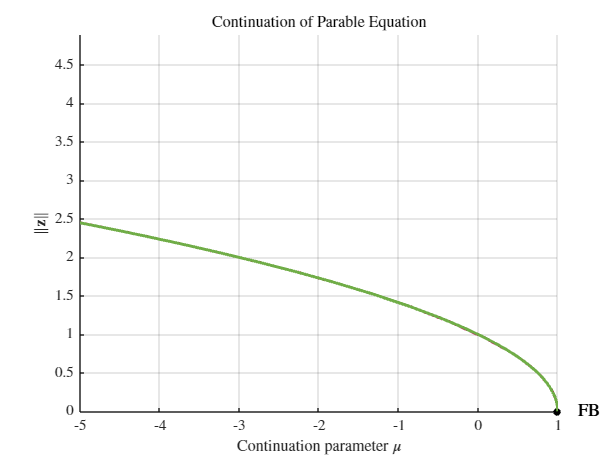

[S,DYN] = costar(options);

Apart from the figure plot, CoSTAR displays information in the command window during the computation:

- At the beginning, the iteration process of `fsolve` trying to find the initial solution (first point on the curve) is shown.

- As soon as `fsolve` succeeded, CoSTAR announces` Initial solution found!`. If the stability of a solution is additionally computed, the message is supplemented by the information `(stable)` or `(unstable)`.

- After that, the continuation starts and CoSTAR displays

              for the latest five computed solutions.

                $\rightarrow$ `Iter: <XXX> `depicts the number of the computed point on the curve. Please keep in mind that the initial solution is counted as `Iter = 1`.

                $\rightarrow$ `mu = <XXX> `shows the value of the continuation parameter $\mu$ for the related point on the curve.

                $\rightarrow$ `stepwidth = <XXX> `displays the step width that was used to compute the point on the curve.

                $\rightarrow$ `(un)stable `reports whether the solution is stable or unstable if the stability was computed.

- Finally, CoSTAR reports the reason of termination.

Please note that the command window output described above is the default output and it may change if the `options.opt_sol` field `'display'` is manually set.

Furthermore, a log file named `CoSTAR_Log_ID_yyyy-mm-dd_hh.mm.ss` (`yyyy-mm-dd` and `hh.mm.ss` show the date and time of day when the computation started) is created in the current directory of MATLAB, giving a more in-depth view of the computation.

## 1.3  Postprocessing

As you might have noticed, CoSTAR automatically plots the Euclidean norm of the state space vector (which is a scalar in this case) $\Vert \mathbf z \Vert$. That is why we do not see the parable yet. In order to change the vertical axis and to plot $z$ against $\mu$, we need to call the `contplot` postprocessing method. Similar to the `costar` function, `contplot` expects a structure that defines all required options for the plot. 

contplot_options = costaropts('zaxis', @(z) z);

By setting the *mandatory* field `'zaxis' `to` @(z) z`, the state variable $z$ is plotted on the vertical axis.

Now we can call the `contplot` method via

which creates a new continuation plot. The method requires the `DynamicalSystem` class object `DYN` as well as the defined `contplot_options` structure as input arguments. Since `contplot` is a method of the class `Solution`, it has to be called by `S.contplot(...)`. 

`contplot` returns an output structure, whose fields `contplot_output.z` and `contplot_output.mu` store the plotted ordinate (vertical axis) values (the $z$-values in this case) and the corresponding $\mu$-values.

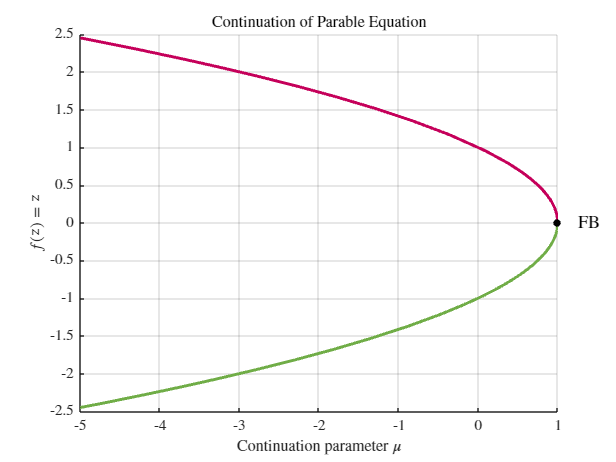

contplot_output = S.contplot(DYN,contplot_options);

Now we can see the parable. The green line shows stable solutions while the red line indicates that these solutions are unstable. The stability changes at the fold bifurcation labeled $\text{FB}$. Please be aware that the complete curve is shown in blue when the stability was not computed.

We do not go into further postprocessing details here as this would exceed the scope of this tutorial. Comprehensive explanations of the postprocessing function `contplot` can be found in the corresponding tutorial and the associated example provides short exemplary code. An overview of the available `contplot` options is given via the `costarhelp` function by typing 

 in the command window. Please note that the postprocessing functions `solget` and `solplot` are not available for equilibrium solutions.

We are done with our first example! Now we move on to the second example *Pitchfork Bifurcation*.

# 2  The Pitchfork Bifurcation Example

clear variables; clc; close all;                    % Let's clean our "desk" before we begin with our second example.

## 2.1 Introduction

The second example we consider is the *pitchfork bifurcation*, whose normal form is given by


$$f: \mathbb R^2 \rightarrow \mathbb R \quad \text{with} \quad 0 = f(z,\mu) = \mu \cdot z - z^3 \, . \quad (2)$$


Again, $z$ corresponds to the state variable and $\mu$ is the continuation (bifurcation) parameter. The bifurcation point is located at $(z^*,\mu^*) = (0,0)$.

In CoSTAR, equation $(2)$ is defined by the function `pitchfork_ap`, but this function sets$f(z,\mu) =  \mu \cdot z - z^3 + \gamma$ in order to be able to investigate imperfections as well. Thus, we set the additional parameter $\gamma = 0$ to obtain equation $(2)$.

gamma = 0;

As in the *Parable* example, we want to compute the set of solutions of equation $(2)$ by executing a path continuation and plot $z$ against $\mu$. This time, however, we need to carry out two continuations.

**Note:** In the following it is assumed that you have gone through the *Parable* example as well as that you know how the pitchfork bifurcation looks like! If you have not worked through the *Parable* example yet, please do so before continuing with this example. If you do not know how the pitchfork bifurcation looks like, just scroll down and take a look at the undermost plot.

## 2.2 Continuation 1

### 2.2.1 Setting useful variables

mu_limit = [-1.5, 1.5];                             % This time, we set the continuation limits to [-1.5, 1.5].
mu0 = mu_limit(1);                                  % Like before, we want to begin the continuation at the bottom limit of mu.

We can already see from equation $(2)$ that $z=0$ is a solution, so we set the initial value to

IC = 0;

As a result, `fsolve` does not need to iterate to the first point on the curve. 

Fcn =  @(z,param) pitchfork_ap(z,param);            % Fcn contains the right-hand side of 0 = f(z,mu).

**Task:** Open the function `pitchfork_ap` and have a look at the definitions. How does the `param` array need to be defined and what is the correct value of the variable `active_parameter`? 

**Answer: **Based on the definitions in `pitchfork_ap`, `param` has to consist of the two parameters $\mu$ and $\gamma$ in that particular order. Since $\mu$ is the first parameter within the array, the value of `active_parameter` must be equal to `1`.

param = {mu0, gamma};
active_parameter = 1;

### 2.2.2 The CoSTAR settings

Now we can set the `options` structures. As in the *Parable* example, we need `options.system`, `options.opt_sol`, `options.opt_init` and `options.opt_cont`.

options1.system   = costaropts('order',0,'dim',1,'rhs',Fcn,'param',param,'info','Continuation of Pitchfork Bifurcation - Part 1');
options1.opt_sol  = costaropts('sol_type','equilibrium','cont','on','stability','on','act_param',active_parameter);
options1.opt_init = costaropts('ic',IC);
options1.opt_cont = costaropts('mu_limit',mu_limit);

Overall, the settings are fairly identical to the previous example. We know that one branch will change its stability behaviour during the continuation, which is why we set  `options1.opt_sol.stability` to `'on'`(for more information on computing the stability of solutions, please see the stability tutorial.) For more information on the `options` structure fields, please use the `costarhelp` function.

### 2.2.3 Running CoSTAR

In the next step, we can already call CoSTAR.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                 CoSTAR                                  %
%              Continuation of Solution Torus AppRoximations              %
%                             Version 2.8.1                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
fsolve is trying to find an initial solution ...

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                   0                               0              1

Equation solved. The final point is the initial point.
The sum of squared function values, r = 0.000000e+00, is less than sqrt(options.FunctionTolerance) = 1.000000e-03.
The relative norm of the gradient of r, 0.000000e+00, is less than o

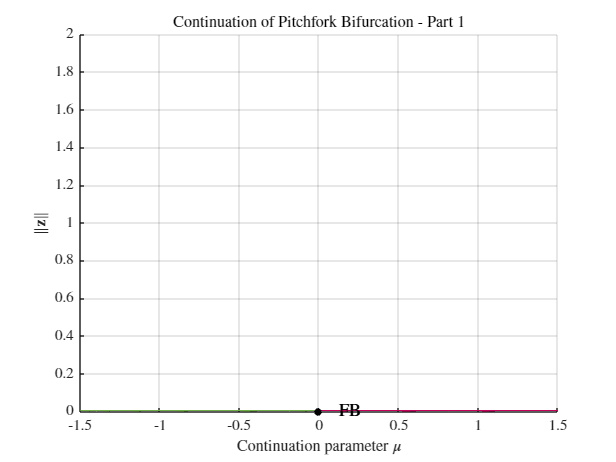

 
CoSTAR stopped because maximal value of continuation parameter mu_max = 1.5 was reached.
 
-----------------------------------------------------
-------------- Successfully finished! ---------------
-----------------------------------------------------
 
 


[S1,DYN1] = costar(options1);

As you can see, CoSTAR is not able to automatically continue multiple branches yet. Only the solution branch $z = 0$ is displayed. For $\mu < 0$, the green line indicates that the solution is stable, while for $\mu > 0$, the red line shows that the solution is unstable. At $\mu = 0$, CoSTAR has detected a bifurcation point, which is labeled as $\text{FB}$ (this can be a fold, pitchfork or transcritical bifurcation).

To compute the top and bottom branches for $\mu\geq 0$, we need to set up a second continuation.

## 2.3 Continuation 2

Most of the settings needed for the second continuation can be taken from the continuation above. However, we need to make some adjustments in order to compute the missing branches via a single continuation.

**Question**: How does `mu0` and `IC` need to be defined in order to compute the missing branches via a single continuation?

**Explanation for **`mu0`**:** As we want to compute the missing branches via a single continuation, we obviously need to start at the upper limit of $\mu$.

**Explanation for **`IC`**:** The initial point for the solver `fsolve` to find the first point on the branch must be close enough to the branch so that `fsolve` converges to the desired branch. For example, when setting `IC = 0.5`, `fsolve` converges to the already computed solution $z = 0$.

mu0 = mu_limit(2);
IC = 1;

Apart from `mu0`, `IC` and the field `'info'`, we need to change the direction of the continuation at the start by setting the field `'direction'` of the `opt_cont` structure to `-1`. This is required here, because CoSTAR always starts to continue the curve in positive $\mu$ direction by default (`'direction' = 1`). However, CoSTAR must begin this continuation in negative $\mu$ direction since we start at the upper limit of $\mu$. You can try to not set `'direction'` to `-1`, but the continuation would stop almost immediately (pay attention to the termination message).

param = {mu0, gamma};           % mu0 changed, so we need to update param
options2.system   = costaropts('order',0,'dim',1,'rhs',Fcn,'param',param,'info','Continuation of Pitchfork Bifurcation - Part 2');  
options2.opt_sol  = costaropts('sol_type','equilibrium','cont','on','stability','on','act_param',active_parameter);
options2.opt_init = costaropts('ic',IC);
options2.opt_cont = costaropts('mu_limit',mu_limit,'direction',-1);

Now we have set the required options to compute the missing branches.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                 CoSTAR                                  %
%              Continuation of Solution Torus AppRoximations              %
%                             Version 2.8.1                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
fsolve is trying to find an initial solution ...

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                0.25                            0.75              1
     1          6            0.137174       0.333333             1.42              1
     2          9          0.00132776      0.0966183            0.113              1
     3         12          2.6505e-07      0.0117985          0.00155              1
     4         15         1.16936e-14    0.000171538      

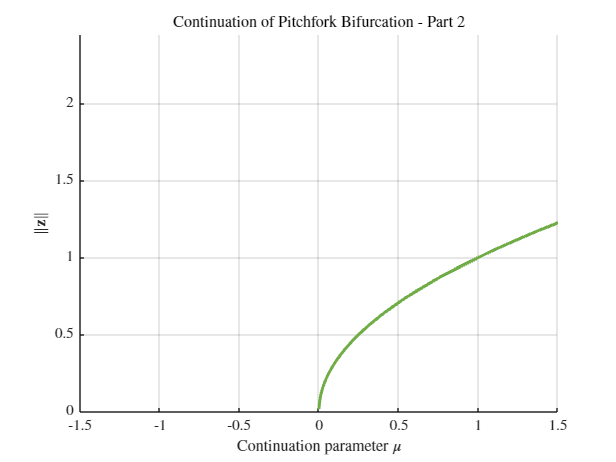

 
CoSTAR stopped because maximal value of continuation parameter mu_max = 1.5 was reached.
 
-----------------------------------------------------
-------------- Successfully finished! ---------------
-----------------------------------------------------
 
 


[S2,DYN2] = costar(options2);

## 2.4 Postprocessing

In order to see the typical pitchfork bifurcation diagram, we need to create a new plot in which we depict $z$ (and not $\Vert \mathbf z \Vert$) on the vertical axis. We already know how to do that and call the `contplot` method of the solution object `S1`. This will create a plot in which the solution branch $z = 0$ is displayed in a diagram depicting z on the vertical axis.

contplot_options_1 = costaropts('zaxis', @(z) z);
contplot_output_1  = S1.contplot(DYN1,contplot_options_1);

Now we need to complement the plot by the second continuation in order to obtain the desired diagram. This is done by calling the `contplot` method of `S2` and setting the `contplot_options` field `'figure'` to the current figure handle `gcf`. Of course, we must not forget to set the field `'zaxis'` appropriately.

contplot_options_2 = costaropts('zaxis', @(z) z, 'figure', gcf);
contplot_output_2  = S2.contplot(DYN2,contplot_options_2);

Unfortunately, the last `contplot` call displaced the horizontal axis limits. Therefore, we rescale the limits of the horizontal axis to the limits of $\mu$.

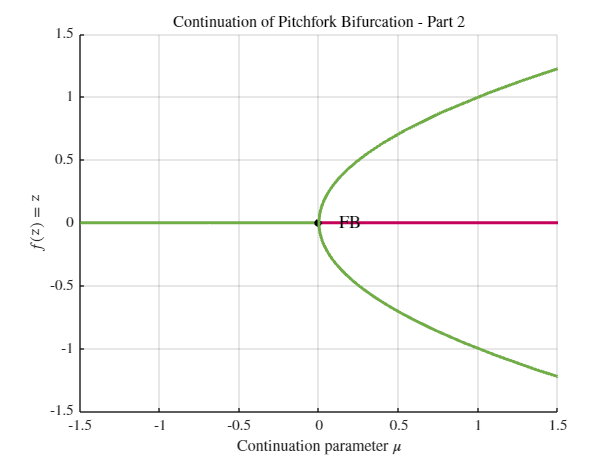

xlim(mu_limit)

We do not go into further postprocessing details here as this would exceed the scope of this tutorial. Comprehensive explanations of the postprocessing function `contplot` can be found in the corresponding tutorial and the associated example provides short exemplary code. An overview of the available `contplot` options is given via the `costarhelp` function by typing 

 in the command window. Please note that the postprocessing functions `solget` and `solplot` are not available for equilibrium solutions.

Finally, we are done with the *Pitchfork Bifurcation* example!

# Final Words

The CoSTAR tutorial on computing equilibrium solutions is now finished. Please keep in mind the `costarhelp` feature which you can use if you need a quick overview and a short description of the available `options` structures and fields.

If you are interested in learning about further capabilities of CoSTAR, you are invited to have a look at the other tutorials as well.

***See you soon!***